## Load Robot Model and Environment

[franka,config,env] = exampleHelperLoadPickAndPlaceRRT;

Visualize the robot model's collision meshes and the environment objects.

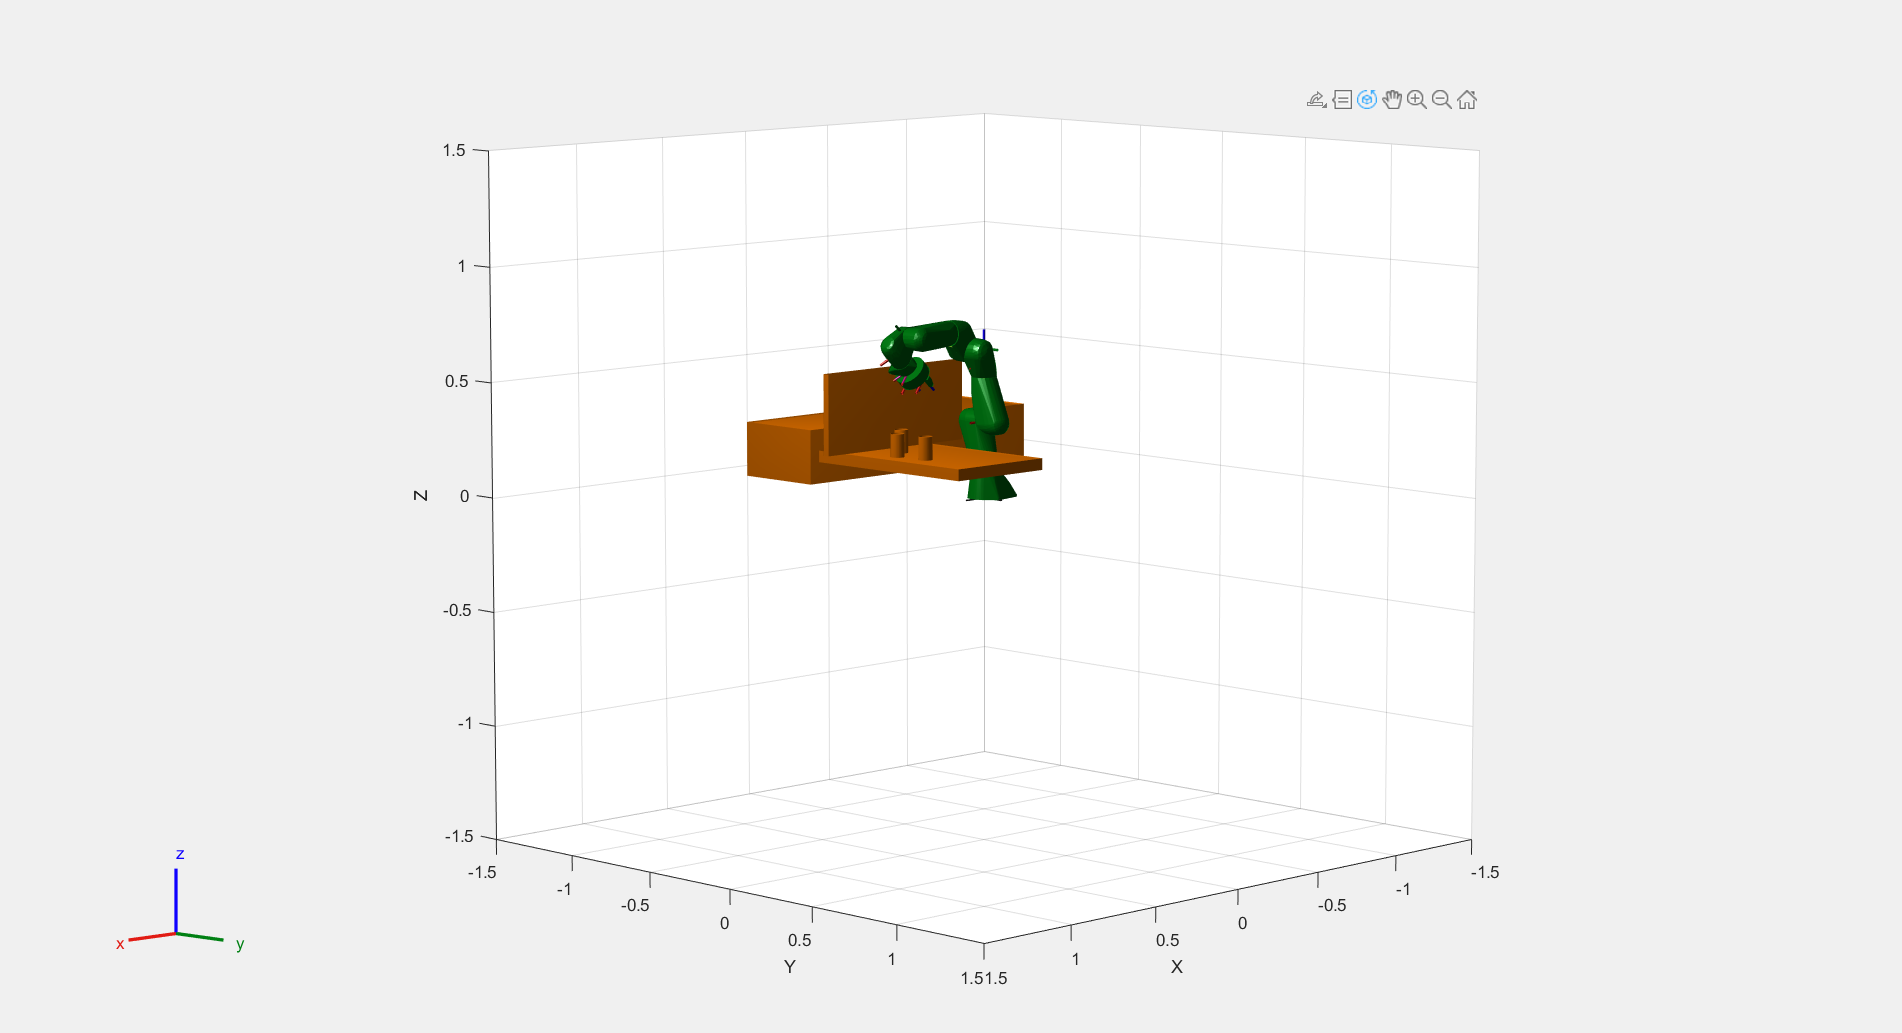

figure("Name","Pick and Place Using RRT",...
    "Units","normalized",...
    "OuterPosition",[0, 0, 1, 1],...
    "Visible","on");
show(franka,config,"Visuals","off","Collisions","on");
hold on
for i = 1:length(env)
    show(env{i});
end

## Planner

Create the RRT path planner and specify the robot model and the environment. Define some parameters, which are later tuned, and specify the start and goal configuration for the robot.

planner = manipulatorRRT(franka, env);
planner.SkippedSelfCollisions='parent';

planner.MaxConnectionDistance = 0.3;
planner.ValidationDistance = 0.1;

startConfig = config;
goalConfig = [0.2371   -0.0200    0.0542   -2.2272    0.0013    2.2072   -0.9670    0.0400    0.0400];

rng('default');
path = plan(planner,startConfig,goalConfig);

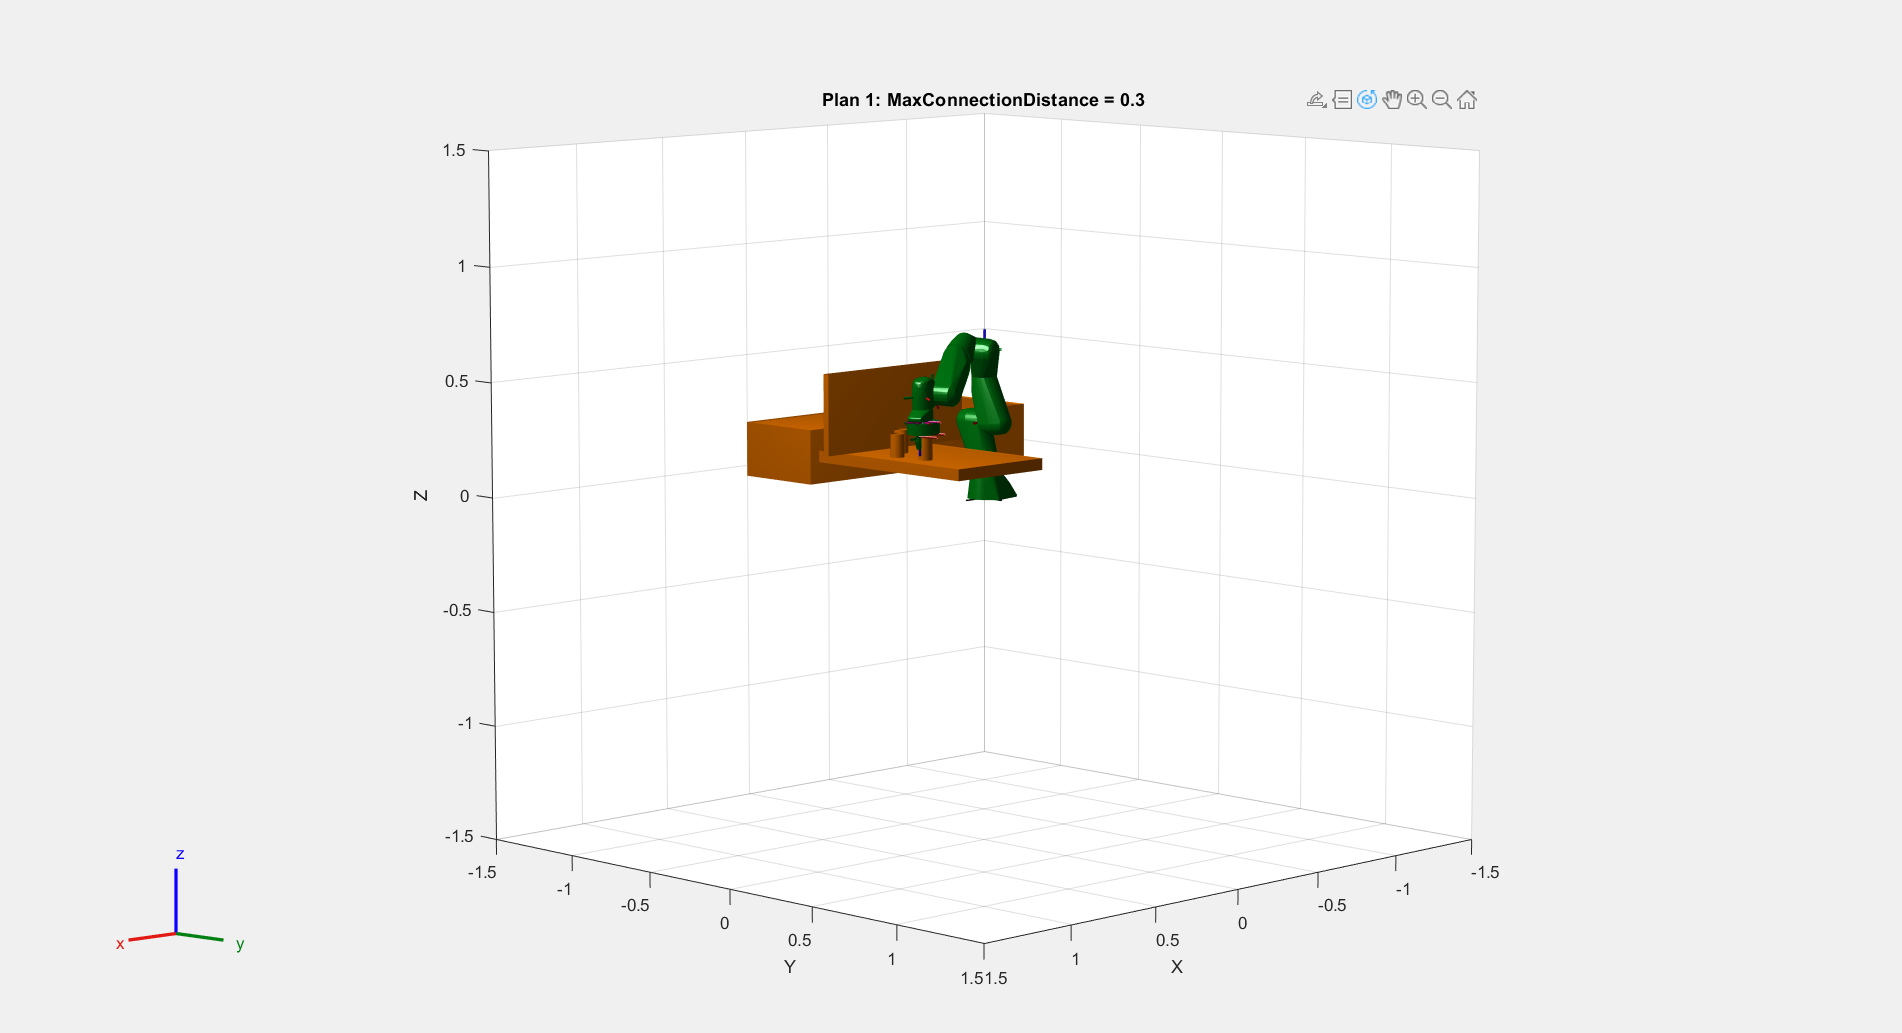

interpStates = interpolate(planner, path);

for i = 1:2:size(interpStates,1)
    show(franka, interpStates(i,:),...
        "PreservePlot", false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 1: MaxConnectionDistance = 0.3")
    drawnow;
end

## Tuning the Planner

planner.MaxConnectionDistance = 5;
tic
path = plan(planner,startConfig,goalConfig);
toc

Elapsed time is 0.420287 seconds.


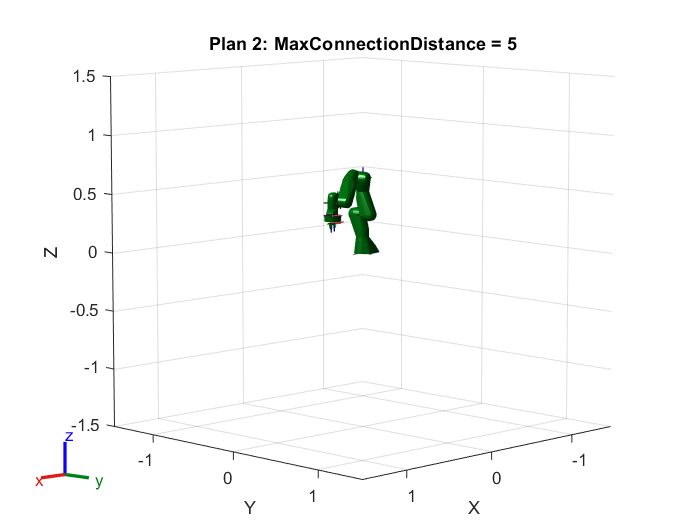

interpStates = interpolate(planner, path);

for i = 1:2:size(interpStates, 1)
    show(franka,interpStates(i,:),...
        "PreservePlot",false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 2: MaxConnectionDistance = 5")
    drawnow;
end

planner.MaxConnectionDistance = 0.3;
planner.ValidationDistance = 0.01;

tic
path = plan(planner,startConfig,goalConfig);
toc

Elapsed time is 0.454656 seconds.


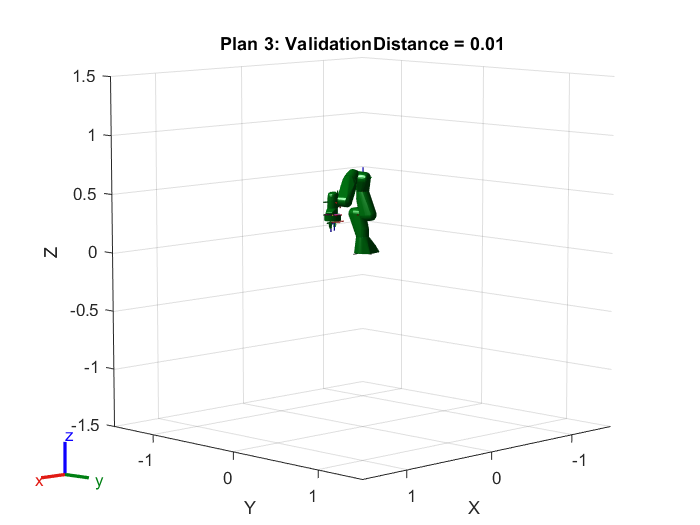

interpStates = interpolate(planner,path);
for i = 1:10:size(interpStates,1)
    show(franka, interpStates(i,:),...
        "PreservePlot",false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 3: ValidationDistance = 0.01")
    drawnow;
end

planner.ValidationDistance = 0.1;
planner.EnableConnectHeuristic = false;

tic
path = plan(planner,startConfig,goalConfig);
toc

Elapsed time is 0.120403 seconds.


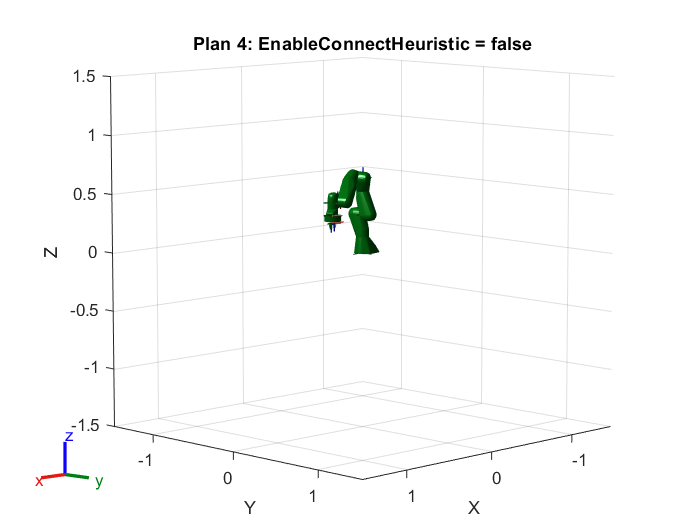

interpStates = interpolate(planner,path);
for i = 1:2:size(interpStates,1)
    show(franka, interpStates(i,:), ...
        "PreservePlot",false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 4: EnableConnectHeuristic = false")
    drawnow;
end

## Attach the Can to the End-Effector

% Create can as a rigid body
cylinder1 = env{3};
canBody = rigidBody("myCan");
canJoint = rigidBodyJoint("canJoint");

% Get current pose of the robot hand.
startConfig = path(end, :);
endEffectorPose = getTransform(franka,startConfig,"panda_hand");

% Place can into the end effector gripper.
setFixedTransform(canJoint,endEffectorPose\cylinder1.Pose); 

% Add collision geometry to rigid body.
addCollision(canBody,cylinder1,inv(cylinder1.Pose));
canBody.Joint = canJoint;

% Add rigid body to robot model.
addBody(franka,canBody,"panda_hand");

% Remove object from environment.
env(3) = [];

goalConfig = [-0.6564 0.2885 -0.3187 -1.5941 0.1103 1.8678 -0.2344 0.04 0.04];
planner=manipulatorRRT(franka, env);
planner.SkippedSelfCollisions='parent';
planner.MaxConnectionDistance = 1;
planner.ValidationDistance = 0.2;
planner.EnableConnectHeuristic = false;
path = plan(planner,startConfig,goalConfig);

interpStates = interpolate(planner,path);

hold off

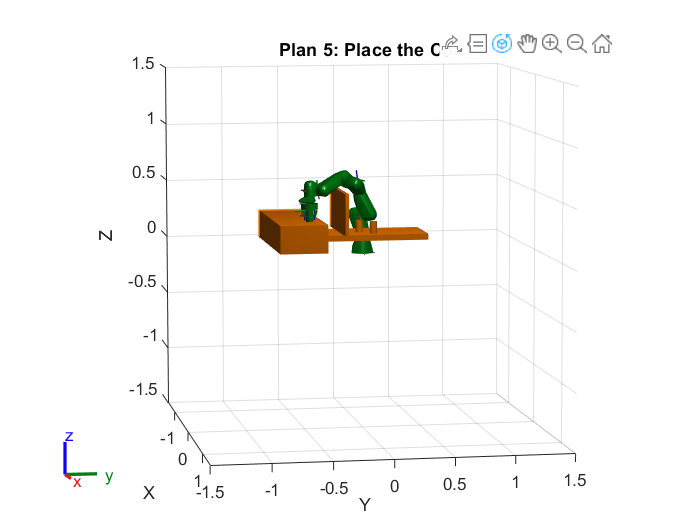

show(franka,config,"Visuals","off","Collisions","on");
hold on
for i = 1:length(env)
    show(env{i});
end

for i = 1:size(interpStates,1)
    show(franka,interpStates(i,:),...
        "PreservePlot", false,...
        "Visuals","off",...
        "Collisions","on");
    title("Plan 5: Place the Can")
    drawnow;
    if i == (size(interpStates,1))
        view([80,7])
    end
end

### Path Optimization

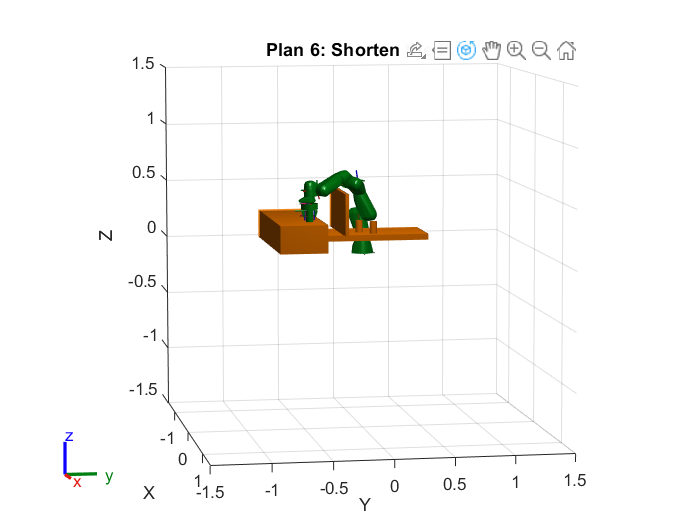

shortenedPath = shorten(planner,path,20);


interpStates = interpolate(planner,shortenedPath);
for i = 1:size(interpStates,1)
    show(franka, ...
        interpStates(i, :),  ...
        "PreservePlot", false, ...
        "Visuals", "off", ...
        "Collisions", "on");
    drawnow;
    title("Plan 6: Shorten the Path")
    if i > (size(interpStates,1)-2)
        view([80,7])
    end
end
hold off

*Referances: MATLAB Robotics Toolbox *